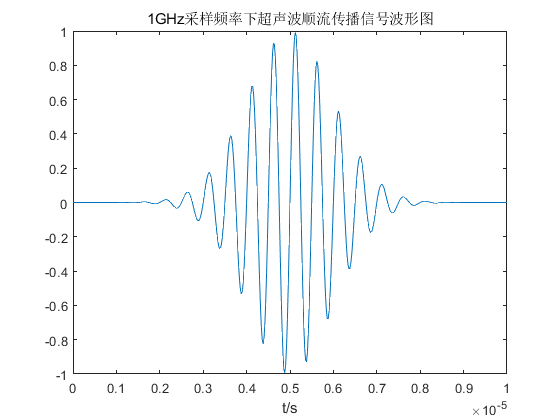

clear;
close all;
% 顺流信号
r = 1e12;
tau = 5e-6;
f = 2e6;
%fs = 1e9;
fs = 50e6;
t = 0:1/fs:2*tau;
s_12 = sin(2*pi*f .* t) .* exp(-r * (t - tau).^2 ./ 2);
figure;
plot(t,s_12);
xlim([0, 2*tau]);
xlabel('t/s');
title('1GHz采样频率下超声波顺流传播信号波形图')

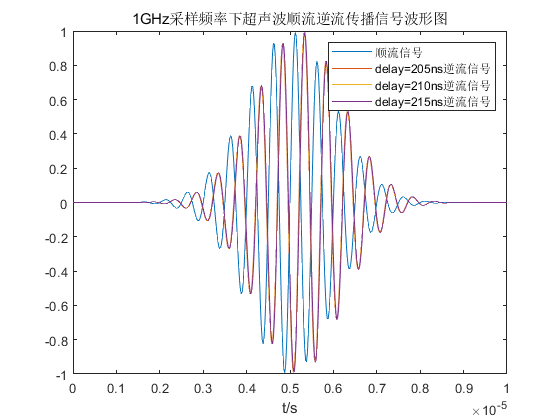



% 逆流信号
delay = [205e-9, 210e-9, 215e-9];
s21 = [];
for i = 1:3
    s = sin(2*pi*f .* (t - delay(i))) .* exp(-r * (t - delay(i) - tau).^2 ./ 2);    
    s21 = [s21;s];
end

figure;
plot(t,s_12);
for i = 1:3
    hold on;
    plot(t ,s21(i, :));
end
xlim([0, 2*tau]);
xlabel('t/s')
title('1GHz采样频率下超声波顺流逆流传播信号波形图')
legend('顺流信号','delay=205ns逆流信号','delay=210ns逆流信号','delay=215ns逆流信号')

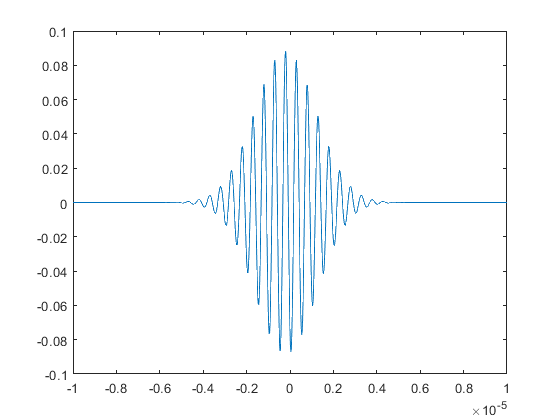

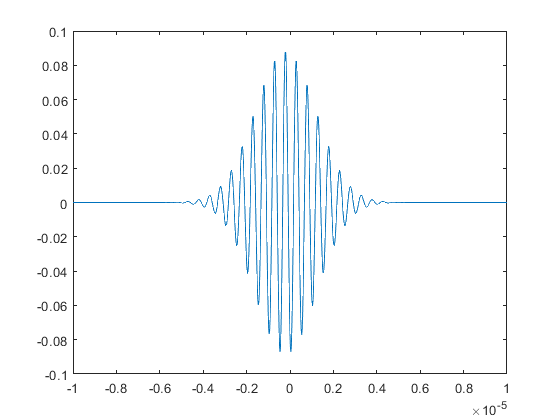

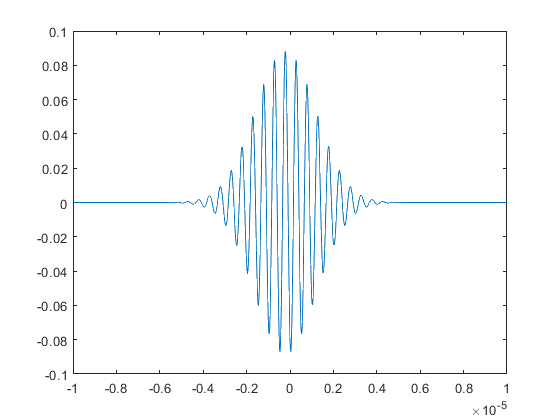

delay_pred = [];
% 利用相关性测时差
for i = 1:3
    [r0, lags] = xcorr(s_12,s21(i, :));
    figure;
    plot(lags / fs ,r0/length(s_12));
    xlim([-2*tau, 2*tau]);
    [ytmp,ttmp] = max(r0);
    delay_pred = [delay_pred; lags(ttmp) / fs];
end